n = 4;
z_shift=0;
m1 = -sqrt(5/8);
m2 = 1/sqrt(8);
m3 = 1/sqrt(16)+z_shift;
sd1 = 1;
sd2 = 1;
sd3 = 1;
rng(13);
DataX = normrnd(m1,sd1,[n,1]);
DataY = normrnd(m2,sd2,[n,1]);
DataZ = normrnd(m3,sd3,[n,1]);

num_iters = 10000;
burn_in = 5000;
proposal_scale = 0.01

proposal_scale = 0.0100

initial_guess=[1/sqrt(4);1/sqrt(4);(1/sqrt(2)+z_shift)]

initial_guess =     0.5000
    0.5000
    0.7071



ll_function = @(x) ll_density(x,sd1,sd2,sd3,DataX,DataY,DataZ,z_shift);
constraintFunc = @(x) (x(1)^2+x(2)^2+(x(3)-z_shift)^2-1);
dConstraintFunc = @(x) ([2*x(1);2*x(2);2*(x(3)-z_shift)]);

[samples, accepts] = runConstrainedMH(num_iters, burn_in, ...
    proposal_scale, initial_guess, ll_function, ...
    constraintFunc, dConstraintFunc)

samples =    -0.3512   -0.4577   -0.4881   -0.4439   -0.4851   -0.5237   -0.5237   -0.3217   -0.4832   -0.5475   -0.5387   -0.5257   -0.6896   -0.5626   -0.6914   -0.6822   -0.7104   -0.7533   -0.7533   -0.7359   -0.7360   -0.6986   -0.6996   -0.6953   -0.7593   -0.6545   -0.6637   -0.6985   -0.5245   -0.5186   -0.5783   -0.6443   -0.5773   -0.5884   -0.5056   -0.4233   -0.5349   -0.4917   -0.3645   -0.3384   -0.4255   -0.3917   -0.3917   -0.3917   -0.4028   -0.4348   -0.3641   -0.3919   -0.3345   -0.2386
   -0.9243   -0.8816   -0.8350   -0.8692   -0.8313   -0.8476   -0.8476   -0.9370   -0.8101   -0.6983   -0.6804   -0.6308   -0.5105   -0.4426   -0.3287   -0.3608   -0.4307   -0.4785   -0.4785   -0.4397   -0.4250   -0.5963   -0.4769   -0.5407   -0.4554   -0.5327   -0.6144   -0.6138   -0.6215   -0.6837   -0.5878   -0.4730   -0.5762   -0.5994   -0.4476   -0.4123   -0.3929   -0.4269   -0.4464   -0.3711   -0.2034   -0.3220   -0.3220   -0.3220   -0.2020   -0.1845   -0.2918   -0.2047   -0.157

accepts =      1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     1     1     1     1     1     1


mean(accepts)

ans = 0.9310

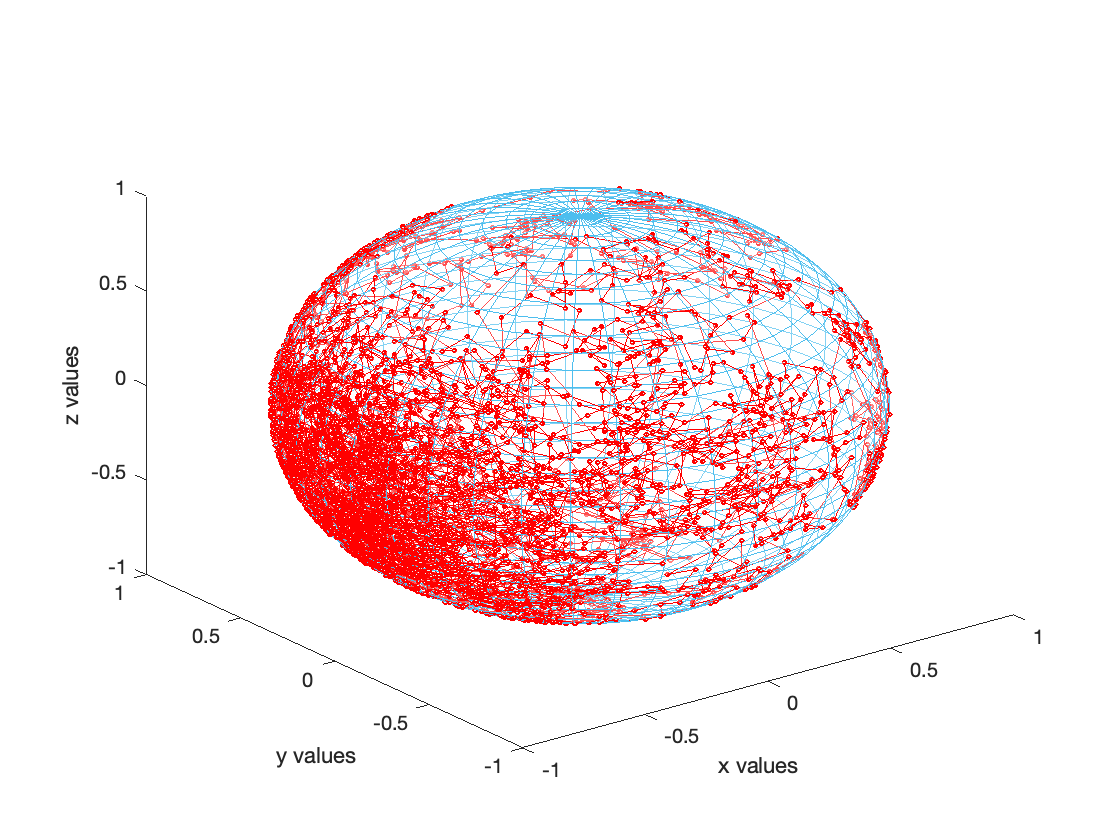

xs=real(samples(1,:))';
ys=real(samples(2,:))';
zs=real(samples(3,:))';
dim=size(xs);
plot3(xs,ys,zs,'-o','Color','r','MarkerSize',2,'MarkerFaceColor','#D9FFFF')
hold on
theta=linspace(0,2*pi,40);
phi=linspace(0,pi,40);
[theta,phi]=meshgrid(theta,phi);
rho=1;
x=rho*sin(phi).*cos(theta);
y=rho*sin(phi).*sin(theta);
z=rho*(cos(phi)+z_shift);
mesh(x,y,z,'EdgeColor',[0.3010 0.7450 0.9330],'FaceAlpha',.3)
xlabel('x values') 
ylabel('y values')
zlabel('z values') 
hold off

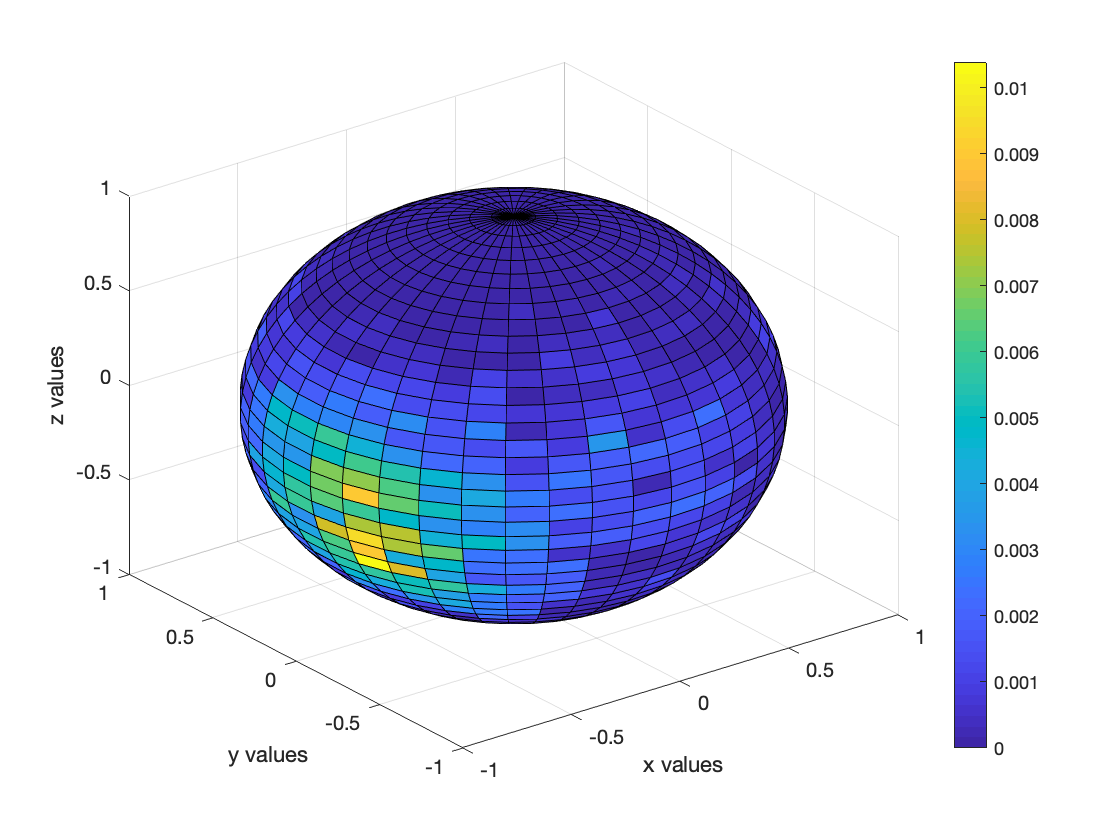

thetas_unshifted=atan(ys./xs);
theta_draws=thetas_unshifted+pi*(xs<0)+...
    2*pi*(xs>0&ys<0);
theta_draws(isnan(theta_draws))=0;
phi_draws=acos(zs-z_shift);

[n,d]=size(theta);
dens2=zeros(n,d);
for t=2:n
    for p=2:d
        x_in= (theta_draws>=theta(p,t-1))&(theta_draws<theta(p,t));
        y_in= (phi_draws>=phi(p-1,t))&(phi_draws<phi(p,t));
        dens2(p,t)=mean(x_in&y_in)*sin(phi(p-1,t-1));
    end
end
s2=surf(x,y,z);
s2.CData=dens2;
xlabel('x values') 
ylabel('y values')
zlabel('z values') 
colorbar

% h = colorbar;
% set(h, 'ylim', [0 0.45])
% hold on
% % plot3(m1-0.05,m2+0.05,m3+0.05,'.','Color','r','MarkerSize',60)
% hold off